#### Project Fintech, group 2

*Bucci Teo*

*Cipriani Filippo*

*Corbo Gabriele*

*Fabroni Davide*

*Lucchini Marco*

# Estimating Clients' Needs

## Aim: supervised classification of clients and association with his/her preferred product

Our goal is to provide a tool for a financial advisor which supports him in suggesting financial products to his clients.

We consider a random extraction of a dataset made up of a wealth manager's customers. The data is anonymous, mostly clean and not always normalized/scaled.

We intend to estimate some **investments needs **for these customers using Data Science techniques: we use a bagged tree, optimized with bayesian optimization. After we proceed with the association of the client with his/her preferred product. 

We use two dataset called "Needs" and "Products".

In the first dataset we have a table **Needs**, with some relevant features and two responses:

- "AccumulationInvest" which is about **Accumulation investing**, typically using dollar-cost averaging (you invest small amounts of your money at certain intervals over the course of time); the response is boolean: 1 = high propensity | 0 = low propensity;

- "IncomeInvest" which is about **Income investing**, typically through lump sum investing (one shot); the response is boolean: 1 = high propensity | 0 = low propensity.

In the latter we have a table** Products**  with some products (funds, segregated accounts, unit-linked), their **type** (1 = Accumulation, 0 = Income), and their **risk level** (normalized in the range [0,1]).

#### *Load data*

close all
clc
clear all
% File loading
load('Needs.mat')
%load('Products.mat')

### **Data transformation of Wealth and Income**

Wealth and Income follow a power law, so it's better to apply some transformation rule.

We chose the box cox transormation, because it's the one that give us the ditribution closer to a normal.

We decided to use an addidional feature, called financial status as a combination of financial education and wealth: we chose this variable because in R we tried many linear models to predict the risk variable associated with each client, and we saw that this particular trasformation was really influent

We will cover this part in more detail in the section Predicting RiskPropension

The descr

Data = Needs; % renaming (we'll likely manipulate this matrix, but we don't touch the original matrix)
Data.FinancialStatus = Data.FinancialEducation.*log(Data.Wealth)

Data = 5000×11 table
    ID    Age    Gender    FamilyMembers    FinancialEducation    RiskPropensity    Income    Wealth    IncomeInvestment    AccumulationInvestment    FinancialStatus
    __    ___    ______    _____________    __________________    ______________    ______    ______    ________________    ______________________    _______________

    1     60       0             2               0.22868             0.23335        68.182     53.26           0                      1                   0.90906    
    2     78       0             2               0.35892             0.17091        21.808    135.55      

[boxWealth,p] = boxcox(Data.Wealth);
p

p = 0.1341

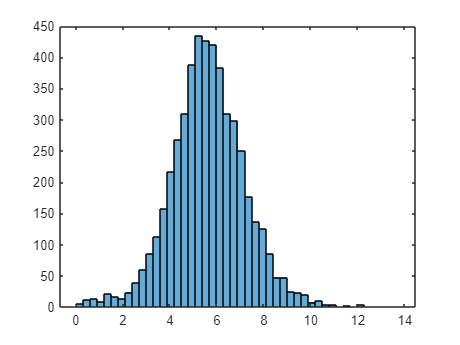

histogram(boxWealth); % box-cox

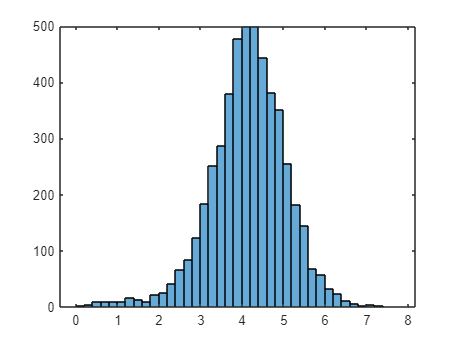

histogram(log(Data.Wealth)) % log transformation

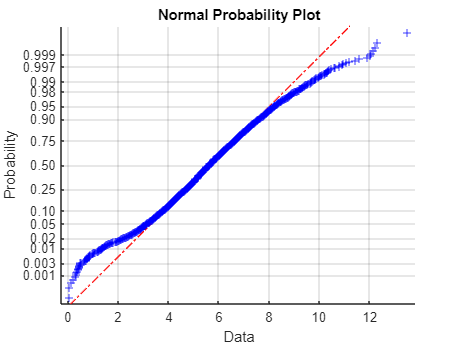

normplot(boxWealth)

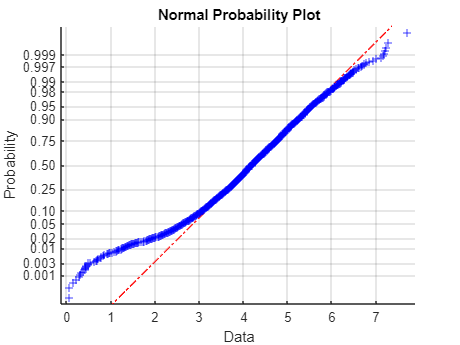

normplot(log(Data.Wealth))  %we chose boxwealth

[boxIncome,p] = boxcox(Data.Income);
p

p = 0.3026

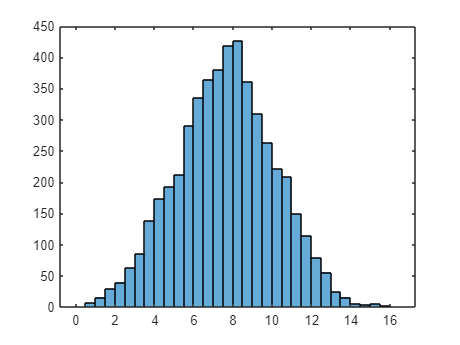

histogram(boxIncome); % box-cox transformation

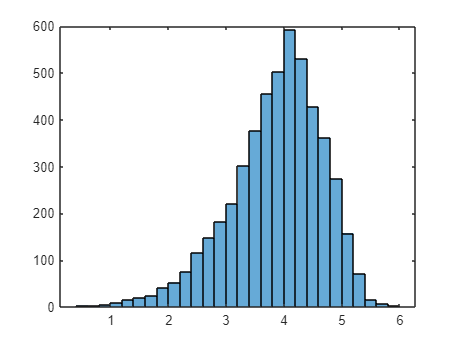

histogram(log(Data.Income)) % log transformation

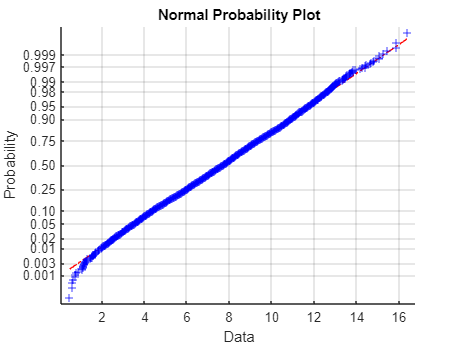

normplot(boxIncome)  % we chose boxIncome

### Adding Time Horizon

Per ora Ho lasciato questo blocco per sicurezza, ma se decidiamo di non usarlo va tolto

We create a Gaussian random vector in the range [1,10] and we assign randomly each value to the clients. This information is saved in the column `InvestmentTimeHorizon.`

%n=6;
%min_timehorizon=1;
%max_timehorizon=10;
%client_time_horizon=floor(min_timehorizon+(max_timehorizon-min_timehorizon)*sum(rand(length(Data.IncomeInvestment),n),2)/n);
%Data.InvestmentTimeHorizon=client_time_horizon(:,1);

### Data scaling

Before applying the machine learning techniques we need to rescale our data in order to make them comparable.

We will use the min/max rescaling approach.

% Min/max rescalation
X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
    rescale(Data.RiskPropensity) rescale(boxIncome) rescale(boxWealth) rescale(Data.FinancialStatus)];

### Classification models

We follow the financial advisory best practice to refine the process:

- accumulation investment products are mainly intended for relatively young people who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older;

- an interesting variable we consider is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture we have eliminated family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important)

### Dividing our data

We divide data in the training sample and test sample. The proportion we use is 75%-25%;

nObs = size(Data, 1);
rng(10)
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
train = 0.75;
cross = 0;

nObsTrain = round(train*nObs);
nObsCross = round(cross*nObs);

XTrain = X(1:nObsTrain,:);
XCross = X((nObsTrain+1):(nObsTrain+nObsCross), :);
XTest = X(nObsTrain+1+nObsCross:end,:);


%********* Aggiunta permutazione delle Y uguale a quella delle X ********
YInc = Data.IncomeInvestment;
YInc = YInc(idxPermutation);

yInvIncTrain = YInc(1:nObsTrain);
yInvIncCross = YInc((nObsTrain+1):(nObsTrain+nObsCross));
yInvIncTest = YInc(nObsTrain+nObsCross+1:end);

YAcc = Data.AccumulationInvestment;
YAcc = YAcc(idxPermutation);

yInvAccTrain = YAcc(1:nObsTrain);
yInvAccCross = YAcc((nObsTrain+1):(nObsTrain+nObsCross));
yInvAccTest = YAcc(nObsTrain+nObsCross+1:end);

varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth','FinancialStatus'};
XTrainTable=table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7),XTrain(:,8), 'VariableNames',varNames);
XTestTable=table(XTest(:,1), XTest(:,2), XTest(:,3), XTest(:,4), XTest(:,5), XTest(:,6),XTest(:,7),XTest(:,8), 'VariableNames',varNames);
XTable=table(X(:,1), X(:,2), X(:,3), X(:,4), X(:,5), X(:,6),X(:,7),X(:,8), 'VariableNames',varNames);

### Fitting the optimized bagged trees

NOTE: it will take a while.

We fit an optimal ensemble of learners for classification: we automatically optimize ensemble hyperparameters using the function `fitcensemble.` It finds hyperparameters that minimize k-fold cross-validation loss (with K=5) by using automatic hyperparameter optimization. As we specify `'OptimizeHyperparameters'`, the function finds optimal parameters automatically using Bayesian optimization.

% Accumulation fitting
rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
%MdlOptimum_acc = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
%    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))
% Income fitting
rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
%MdlOptimum_inc = fitcensemble(XsmallTrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
%    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))
% We save the models
%save("model_accTIME.mat","MdlOptimum_acc");
%save("model_incTIME.mat","MdlOptimum_inc");
load("model_accTIME.mat")
load("model_incTIME.mat")

### Predicting RiskPropension

We think that estimating the parameter risk It's a critical step because It’s a bit unrealistic that a customer knows by himself how much he wants tor risk in a 0-10 scale: for example the popular roboadvisor moneyfarm uses a short questionary to estimate the parameter.

In particular we decided to rely on MiFID (acronym for Directive on Markets in Financial Instruments) that is a Community directive aimed at regulating investment services in the 30 Member States.

The MiFID questionnaire aims to collect as much information as possible relating to the knowledge and experience of a client's investments, investment objectives and financial situation, and it is used as a adequacy and appropriateness questionnaire to find the solution more suitable for the client.

Since some of the parameters asked in the MiFid are contained in the needs dataset, we decided to estimate the risk using a regression learner, in particular the *nome del learner che avete usato* already implemented in matlab.

We used all the parameters except the gender and as already said we added a new feature to improve the accuracy of the model.

Xtopred = X(1:nObsTrain,:);
Xtopred(:,5) = [];
risk = X(1:nObsTrain,5);

XtopredTest = X(nObsTrain+nObsCross+1:end,:);
XtopredTest(:,5) = [];
riskTest = X(nObsTrain+nObsCross+1:end,5);

RiskPred = fitlm(Xtopred,risk)
plot(RiskPred)

yfit = predict(RiskPred, XtopredTest);
MAE = mean(abs(yfit-riskTest));
adjMAE = MAE/range(riskTest);
errors = [MAE adjMAE]

XtopredFull = X;
XtopredFull(:,5) = [];

RiskPred = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)         0.16     0.017334     9.2303       4.4e-20
    x1              -0.32269     0.016991    -18.992    7.3843e-77
    x2             0.0049203    0.0040664       1.21       0.22635
    x3              0.035588     0.010903      3.264     0.0011084
    x4               0.49027     0.047081     10.413    4.7335e-25
    x5             -0.085768     0.017618    -4.8683     1.172e-06
    x6               0.36515     0.048504     7.5282    6.4096e-14
    x7            

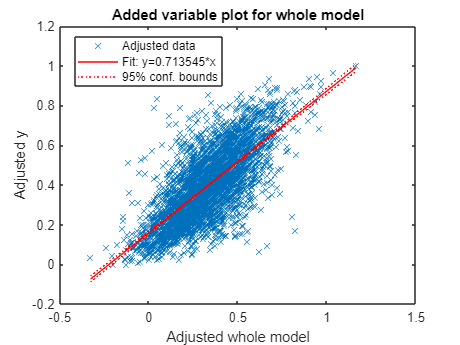

yfit = predict(RiskPred, XtopredFull);


X(:,5)=yfit;

## Prediction

From each ensemble classifier, `MdlOptimum_acc` and `MdlOptimum_inc` we retrieve:

- predicted labels;

- scores (the confidence that an observation originates from a specific class; the higher the score, the higher the confidence;  `Bag` scores range from `0` to `1: `closer they are to 1 better is the performance of the classification model.

We examine scores,which are probabilities averaged over all the trees in the ensemble, in order to understand how strong is the model conviction.

[labels_acc,scores_acc] = predict(MdlOptimum_acc,XsmallTest);

figure

errors =     0.0932    0.0991


histogram(max(scores_acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')
[labels_inc,scores_inc] = predict(MdlOptimum_inc,XsmallTest);

figure
histogram(max(scores_inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

We observe that most scores are close to 1, therefore the model has a strong convinction of its predictions.

### Precision, recall and F1 score for Accumulation need

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the Accumulation need of clients to their true value.

% Accumulation products

Error using classreg.learning.internal.table2PredictMatrix>makeXMatrix (line 86)
Missing value for predictor Financial Education.

Error in classreg.learning.internal.table2PredictMatrix (

tp_acc = sum((labels_acc == '1') & (yInvAccTest=='1'));
fp_acc = sum((labels_acc == '1') & (yInvAccTest=='0'));
fn_acc = sum((labels_acc == '0') & (yInvAccTest=='1'));
prec_acc = tp_acc / (tp_acc + fp_acc)
rec_acc = tp_acc / (tp_acc + fn_acc)
F1_acc = 2 * prec_acc * rec_acc / (prec_acc + rec_acc)

### Precision, recall and F1 score for Accumulation need

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the Income need of clients to their true value.

% Income products
tp_inc = sum((labels_inc == '1') & (yInvIncTest=='1'));
fp_inc = sum((labels_inc == '1') & (yInvIncTest=='0'));
fn_inc = sum((labels_inc == '0') & (yInvIncTest=='1'));
prec_inc = tp_inc / (tp_inc + fp_inc)
rec_inc = tp_inc / (tp_inc + fn_inc)
F1_inc = 2 * prec_inc * rec_inc / (prec_inc + rec_inc)

In both cases the results indicate that the model classifies Accumulation and Income need, since precision, recall and F1 score are quite close to 1.

### ROC curve

[X_acc,Y_acc,T_acc,AUC_acc,OPTROCPT_acc] = perfcurve(yInvAccTest,scores_acc(:,2),1);

Unrecognized function or variable 'labels_acc'.

%area under curve
AUC_acc
plot(X_acc,Y_acc)
hold on
plot(OPTROCPT_acc(1),OPTROCPT_acc(2),'ro')
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Accumulation Need')
hold off
%optimal operating point accumulation
OPTROCPT_acc
%threshold of the optimal operating point
T_acc((X_acc==OPTROCPT_acc(1))&(Y_acc==OPTROCPT_acc(2)))
%income
[X_inc,Y_inc,T_inc,AUC_inc,OPTROCPT_inc] = perfcurve(yInvIncTest,scores_inc(:,2),1);
%area under curve
AUC_inc
plot(X_inc,Y_inc)
hold on
plot(OPTROCPT_inc(1),OPTROCPT_inc(2),'ro')

AUC_acc = 0.8841

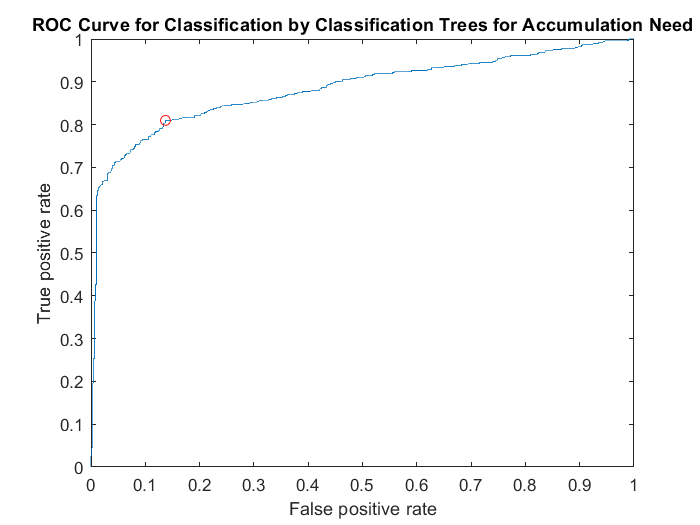

xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Income Need')
hold off
%optimal operating point accumulation
OPTROCPT_inc
%threshold of the optimal operating point

T_inc((X_inc==OPTROCPT_inc(1))&(Y_inc==OPTROCPT_inc(2)))

 The ROC curves show the goodness-of-fit of the model considered. It plots the trade-off between sensitivity (or TPR) and specificity (1 – FPR). 

This curves confirm that our models provide an accurate classification. Moreover the value of the AUC is very close to 1 in both cases.

We observe that the classification of accumulation needs is a bit more accurate than the income ones.

### **Confusion matrices**

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary.

OPTROCPT_acc =     0.1371    0.8098


%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvAccTest,labels_acc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

ans = 0.3840

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary.
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvIncTest,labels_inc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

In both cases the model could be improved by reducing the number of false positives: is predicted 0 (no need of accumulation or income product) instead of a true 1 (a need in one of the two).

## Recommending products

Now we generate the personalized recommendation for both the Accumulation products (that is, Products.Type==1) and for the Income Products (that is, Products.Type==0).

We adopt the following rules, for each client:

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting a list of products**, ranked based on a decreasing risk.

For simplicity and to continue the example, we do that for the clients in the test set (but the rules work for an arbitrary set of clients).

Retrieving IDs and risk propensities for the client in the test set, and products (using the variable idxPermutation).

% Retrieving clients IDs

AUC_inc = 0.8126

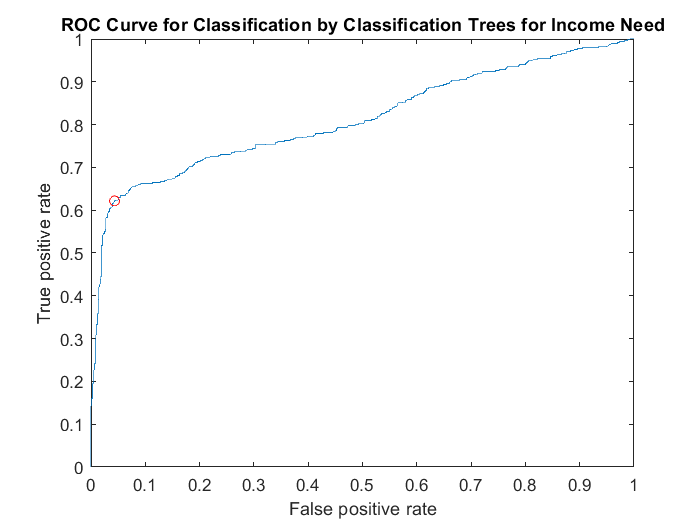

ClientID = Data.ID(idxPermutation);
ClientIDTest = ClientID(nObsTrain+1:end,:);
TargetClientID_acc = ClientIDTest(labels_acc=='1');
TargetClientID_inc = ClientIDTest(labels_inc=='1');

% Retrieving clients' risk propensities
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);

ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity_acc = ClientRiskPropensityTest(labels_acc=='1');

OPTROCPT_inc =     0.0434    0.6217


TargetClientRiskPropensity_inc = ClientRiskPropensityTest(labels_inc=='1');


ans = 0.4815

% Retrieving clients' time horizon
ClientTimeHorizon= Data.InvestmentTimeHorizon(idxPermutation);
ClientTimeHorizonTest = ClientTimeHorizon(nObsTrain+1:end,:);
TargetClientTimeHorizon_acc = ClientTimeHorizonTest(labels_acc=='1');
TargetClientTimeHorizon_inc = ClientTimeHorizonTest(labels_inc=='1');

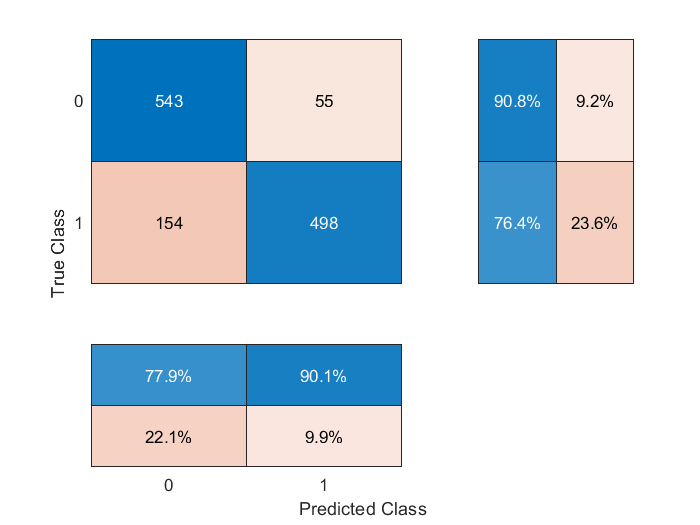

% Let's have a look to risk propensities and time horizon
figure

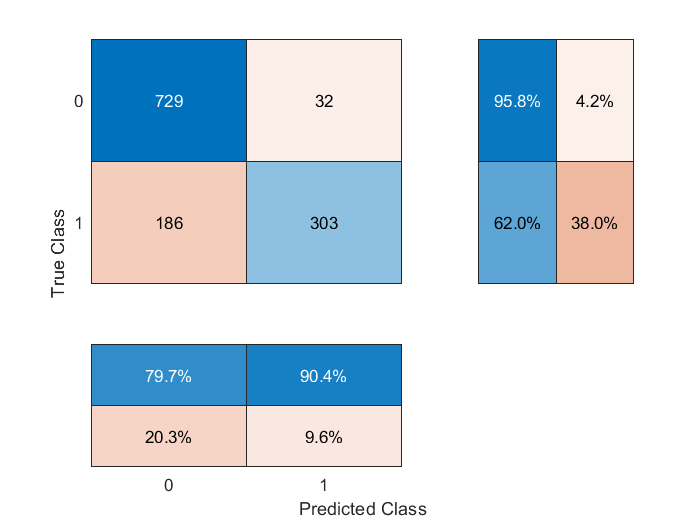

histogram(TargetClientRiskPropensity_acc, 'FaceColor', 'r')
title('Risk Propensity of target clients acc')
xlabel('Risk propensity')

ylabel('Frequency')

figure
histogram(TargetClientTimeHorizon_acc, 'FaceColor', 'r')
title('Time horizon of target clients acc')
xlabel('Time horizon')
ylabel('Frequency')

### Add products Time Horizon

We assign to each product category the time horizon of investment.

In brief, we have assigned, for Income Products:

- Income Conservative Unit-Linked (Life Insurance) : 5 years;

- Fixed Income Mutual Fund: 8 years;

- Balanced High Dividend Mutual Fund: 7 years;

- Fixed Income Segregated Account: 8 years;

- Term deposits: 2 years.

We have assigned, for Accumulation Products:

- Balanced Mutual Fund: 5 years;

- Balanced Mutual Fund: 5 years;

- Defensive Flexible Allocation Unit-Linked (Life Insurance): 4 years;

- Aggressive Flexible Allocation Unit-Linked (Life Insurance): 7 years;

- Balanced Flexible Allocation Unit-Linkled (Life Insurance): 5 years;

- Cautious Allocation Segregated Account: 6 years;

- Total Return Aggressive Allocation Segregated Account: 9 years.

AccumulationProducts.TimeHorizon=[5 5 4 7 5 6 9]';
IncomeProducts.TimeHorizon=[5 8 7 8 2]';

Products.TimeHorizon = [5 5 8 7 5 4 7 5 6 8 9 2]';
%save("ProductsNEW.mat","Products")
AccumulationProducts = Products(Products.Type == 1,:)
figure
histogram(TargetClientRiskPropensity_inc, 'FaceColor', 'r')
title('Risk Propensity of target clients income')
xlabel('Risk propensity')
ylabel('Frequency')
figure
histogram(TargetClientTimeHorizon_inc, 'FaceColor', 'r')
title('Time horizon of target clients income')
xlabel('Time horizon')
ylabel('Frequency')
IncomeProducts = Products(Products.Type == 0,:)

### Creating the personalized recommandations:

- The suitable products are those with a risk level below the client risk tolerance;

- Among those products, we have done two classification wrt risk level (more risky) and wrt time horizon (difference between time horizon of client and of the products)

- We add to the products also term deposits, which have a very low risk, in order to find a suitable product also for clients with a lower risk propensity. so, we consider clients with still no associated products: a low risk income product deposito a termine

Accumulation clients case:

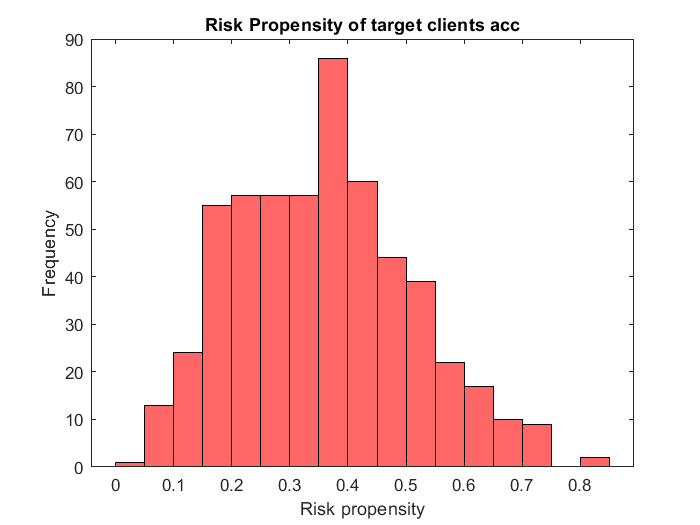

%accumulation
%inizialization
NBA_IDProduct_acc = zeros(length(TargetClientRiskPropensity_acc),3);
NBA_IDProduct_acc_TH = zeros(length(TargetClientRiskPropensity_acc),3);
RecommendedRiskLevel_acc = zeros(size(TargetClientRiskPropensity_acc, 1),3);
RecommendedTimeHorizon_acc= zeros(size(TargetClientRiskPropensity_acc, 1),3);

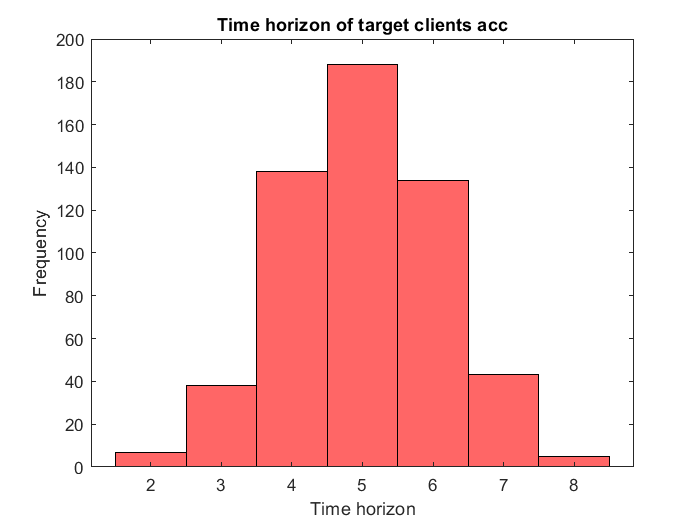

minRisk_acc = min(AccumulationProducts.Risk); %minimun risk for accumulation products

z=1;
%Association products-clients with risk propensity
for i= 1:length(TargetClientRiskPropensity_acc)
    v_1=[];

    M_1=[];
    M_1TH=[];
    v_TH=[];
    if TargetClientRiskPropensity_acc(i)>minRisk_acc %check client risk propensity>minimun risk
        
        for j=1:length(AccumulationProducts.ID)
            if AccumulationProducts.Risk(j)<TargetClientRiskPropensity_acc(i)
                v_1=[v_1 AccumulationProducts.ID(j)];
                M_1=[M_1 AccumulationProducts.Risk(j)];
                M_1TH=[M_1TH AccumulationProducts.TimeHorizon(j)];
            end
        end
        %Association of max 3 products wrt Time horizon

AccumulationProducts = 7×4 table
    ID    Type    Risk    TimeHorizon
    __    ____    ____    ___________

     1     1      0.55         5     
     5     1      0.41         5     
     6     1      0.36         4     
     7     1      0.75         7     
     8     1      0.48         5     
     9     1      0.27         6     
    11     1      0.88         9     


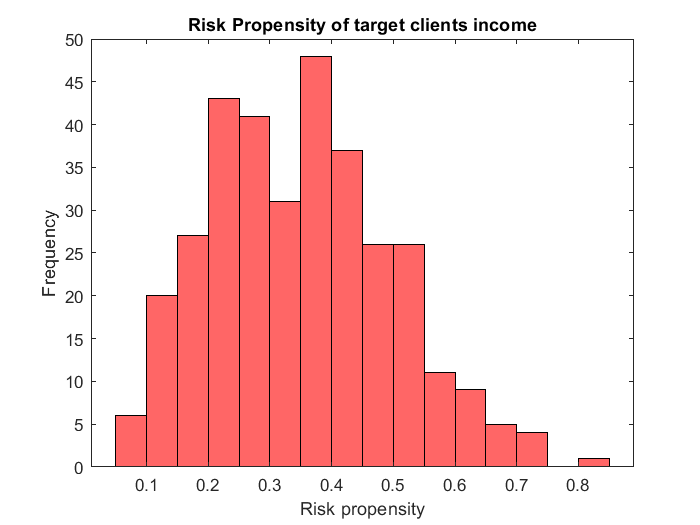

        diff_TH=abs(TargetClientTimeHorizon_acc(i)-M_1TH);
        [~,ord]=sort(diff_TH,'ascend');
        if length(diff_TH)>3
            v_TH(1:3)=v_1(ord(1:3));
            M_TH=M_1TH(ord(1:3));

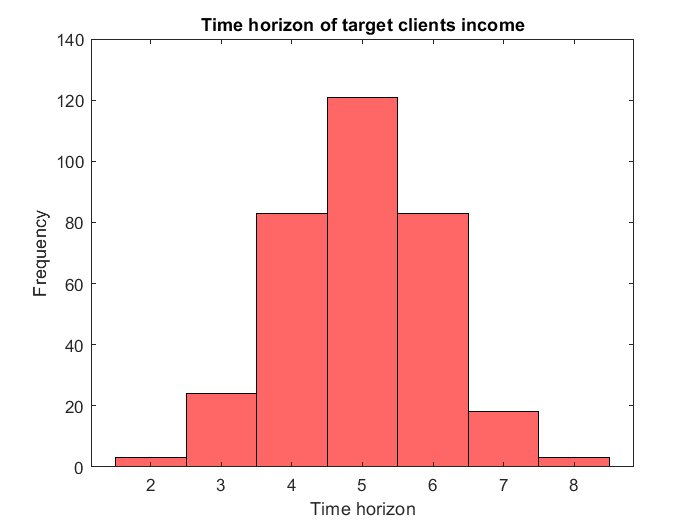

            
        else
            v_TH=v_1(ord);
            M_TH=M_1TH(ord);
        end

        %Association of max 3 products wrt risk propensities

IncomeProducts = 5×4 table
    ID    Type    Risk    TimeHorizon
    __    ____    ____    ___________

     2     0       0.3         5     
     3     0      0.12         8     
     4     0      0.44         7     
    10     0      0.13         8     
    12     0      0.05         2     


        if length(v_1)>3
            [M, Ind]= sort(M_1,"descend"); %choose 3 riskier products
            v(1:3)=v_1(Ind(3:-1:1));
            M=M(3:-1:1);
            
        else
            [M, Ind]= sort(M_1,"ascend");
            v=v_1(Ind);
        end
        NBA_IDProduct_acc(i,1:length(v))=v;
        NBA_IDProduct_acc_TH(i,1:length(v_TH))=v_TH;
        RecommendedRiskLevel_acc(i, 1:length(M))=M;
        RecommendedTimeHorizon_acc(i,1:length(M_TH))=M_TH;
    else
        %clients that cannot be associated (risk too low)
        NONASSOCIATI_acc(z)=TargetClientID_acc(i);
        risk_nonass_acc(z)=TargetClientRiskPropensity_acc(i);
        z=z+1;
    end
end
%NBA_acc collects client_ID and the associated products
NBA_acc=[TargetClientID_acc categorical(NBA_IDProduct_acc)];
NBA_acc_TH=[TargetClientID_acc categorical(NBA_IDProduct_acc_TH)];

%risk_nonassociated_acc collects client_ID and client risk propensity
risk_nonassociated_acc=[double(NONASSOCIATI_acc') risk_nonass_acc' ];
%association of an alternative product DEPOS low risk income
p=1;
q=1;
proposta_alternativa=[];
non_associabili=[];
for k=1:size(risk_nonassociated_acc,1)
    if risk_nonassociated_acc(k,2)>IncomeProducts.Risk(end)
        proposta_alternativa(p,1)=risk_nonassociated_acc(k,1);
        proposta_alternativa(p,2)=risk_nonassociated_acc(k,2);
        p=p+1;
    else
        %clients that have risk lower than depos risk
        non_associabili(q,1)=risk_nonassociated_acc(k,1);
        non_associabili(q,2)=risk_nonassociated_acc(k,2);
        q=q+1;
    end
end
% INCOME
%income products
figure
c = linspace(0,1,length(TargetClientRiskPropensity_acc));
scatter(TargetClientRiskPropensity_acc, max(RecommendedRiskLevel_acc,[],2), [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')

Income clients case:

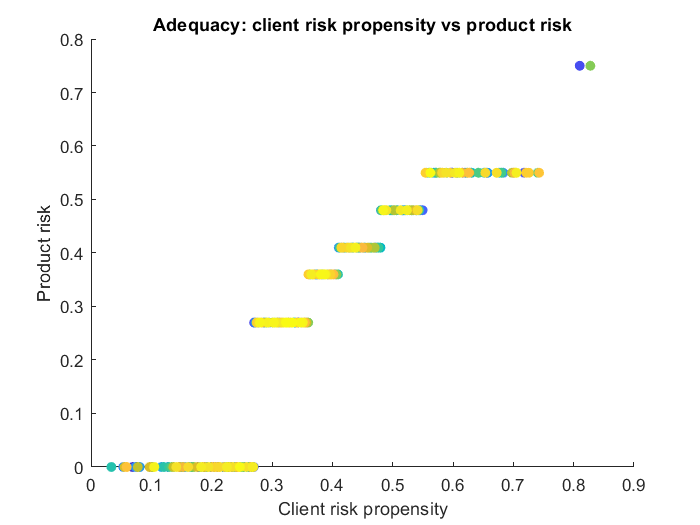

% INCOME
%income products
%inizialization
NBA_IDProduct_inc = zeros(length(TargetClientRiskPropensity_inc),3);
NBA_IDProduct_inc_TH = zeros(length(TargetClientRiskPropensity_inc),3);
RecommendedRiskLevel_inc = zeros(size(TargetClientRiskPropensity_inc, 1),3);
RecommendedTimeHorizon_inc= zeros(size(TargetClientRiskPropensity_inc, 1),3);
minRisk = min(IncomeProducts.Risk(1:4));
z=1;
NONASSOCIATI_inc=[];
%Association products-clients with risk propensity
for i= 1:length(TargetClientRiskPropensity_inc)
    v_1=[];
    M_1=[];
    M_1TH=[];
    v_1TH=[];
    if TargetClientRiskPropensity_inc(i)>minRisk %check client risk propensity>minimun risk
        for j=1:length(IncomeProducts.ID)-1
            if IncomeProducts.Risk(j)<TargetClientRiskPropensity_inc(i)
                v_1=[v_1 IncomeProducts.ID(j)];
                M_1=[M_1 IncomeProducts.Risk(j)];
                M_1TH=[M_1TH AccumulationProducts.TimeHorizon(j)];
                
            end
        end
        %Association of max 3 products wrt risk propensities
        if length(v_1)>3
            [M, Ind]= sort(M_1,"descend"); %choose 3 riskier products
            v(1:3)=v_1(Ind(3:-1:1));
            M=M(3:-1:1);
        else
            [M, Ind]= sort(M_1,"ascend");
            v=v_1(Ind);

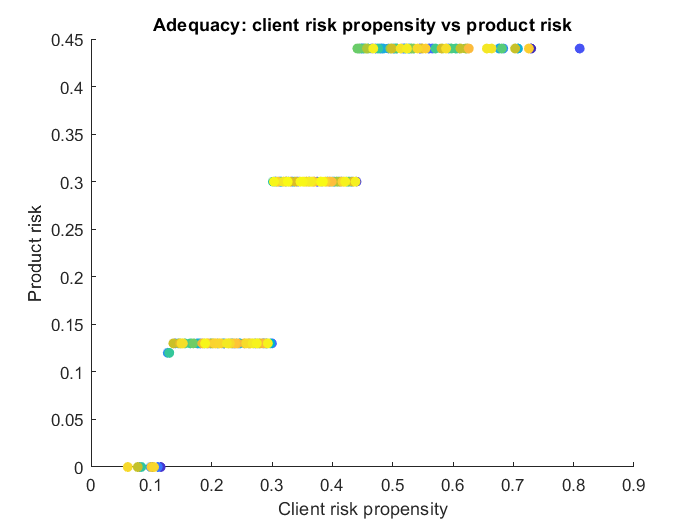

        end
        %Association of max 3 products wrt time horizon
        diff_TH=abs(TargetClientTimeHorizon_inc(i)-M_1TH);
        [~,ord]=sort(diff_TH,'ascend');
        if length(diff_TH)>3
            v_TH(1:3)=v_1(ord(1:3));
            M_TH=M_1TH(ord(1:3));
        else
            v_TH=v_1(ord);
            M_TH=M_1TH(ord);
        end
        NBA_IDProduct_inc(i,1:length(v))=v;
        NBA_IDProduct_inc_TH(i,1:length(v_TH))=v_TH;
        RecommendedTimeHorizon_inc(i, 1:length(M_TH))=M_TH;
        RecommendedRiskLevel_inc(i, 1:length(M))=M;
    else
        NONASSOCIATI_inc(z)=TargetClientID_inc(i);
        risk_nonass_inc(z)=TargetClientRiskPropensity_inc(i);
        z=z+1;
    end
end


%NBA_inc collects client_ID and the associated products
NBA_inc=[TargetClientID_inc categorical(NBA_IDProduct_inc)];
NBA_inc_TH=[TargetClientID_inc categorical(NBA_IDProduct_inc_TH)];

%risk_nonassociated_inc collects client_ID and client risk propensity
risk_nonassociated_inc=[double(NONASSOCIATI_inc') risk_nonass_inc' ];
%association of an alternative product DEPOS low risk income
%starting from clients added from accomulation

p=size(proposta_alternativa,1)+1;
q=length(non_associabili)+1;
for k=1:size(risk_nonassociated_inc,1)
    if risk_nonassociated_inc(k,2)>IncomeProducts.Risk(end)
        proposta_alternativa(p,1)=risk_nonassociated_inc(k,1);
        proposta_alternativa(p,2)=risk_nonassociated_inc(k,2);
        p=p+1;
    else
        %clients that have risk lower than depos risk
        non_associabili(q,1)=risk_nonassociated_inc(k,1);
        non_associabili(q,2)=risk_nonassociated_inc(k,2);
        q=q+1;
    end
end
proposta_alternativa=[proposta_alternativa 12*ones(size(proposta_alternativa,1),1)];

figure
c = linspace(0,1,length(TargetClientRiskPropensity_inc));
scatter(TargetClientRiskPropensity_inc, max(RecommendedRiskLevel_inc,[],2), [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')